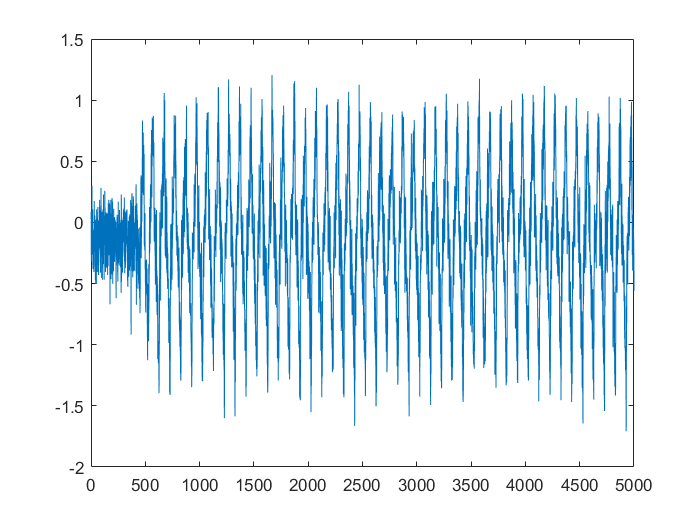

% clear
load("files/switchingAFCMulti.mat")
y = data.y(1:5000);
plot(y)

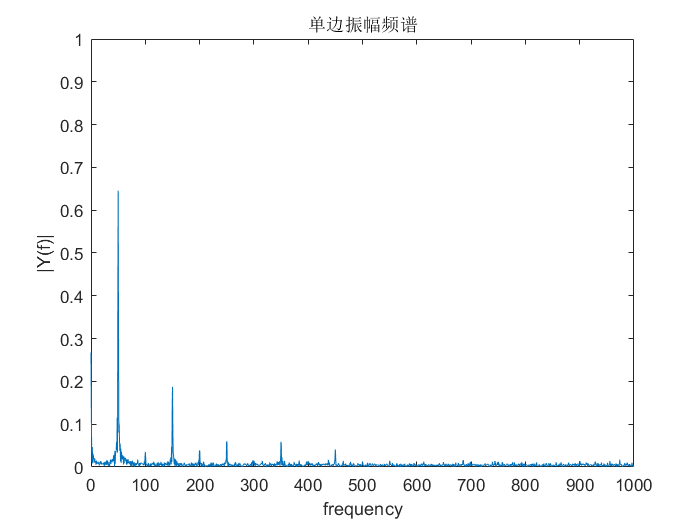


Fs = 5000;

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
ylim([-2, 2])

title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 1000])
ylim([0, 1])

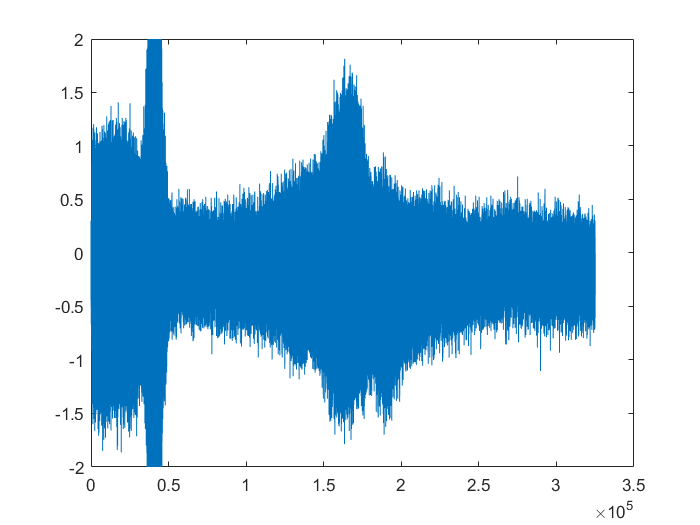

% clear
load("files/bandpass50.mat")
load("files/switchingAFCMulti.mat")
y = data.y(1:end);
plot(y)
ylim([-2, 2])

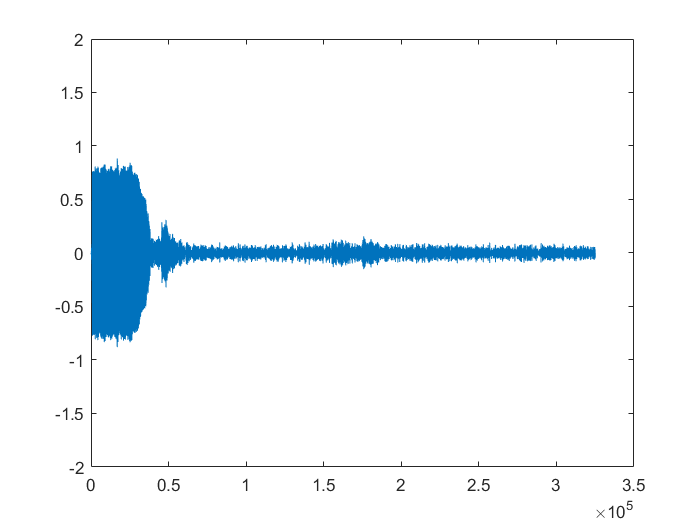


plot(filter(bandpass50,y))
ylim([-2, 2])

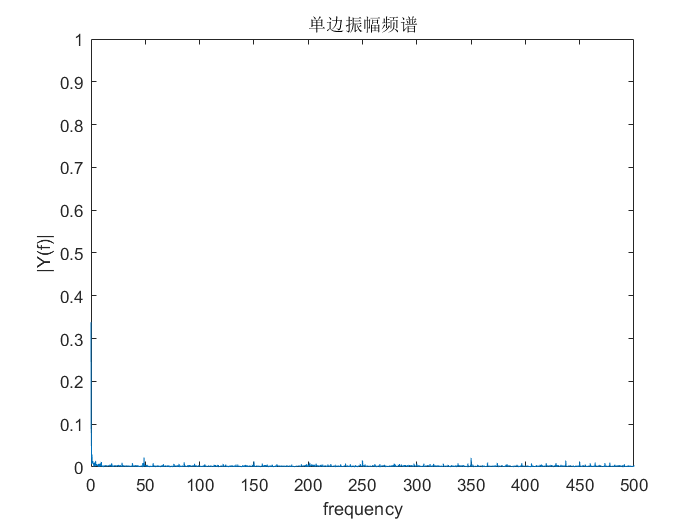

Fs = 5000;

y = data.y(300000:end);

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

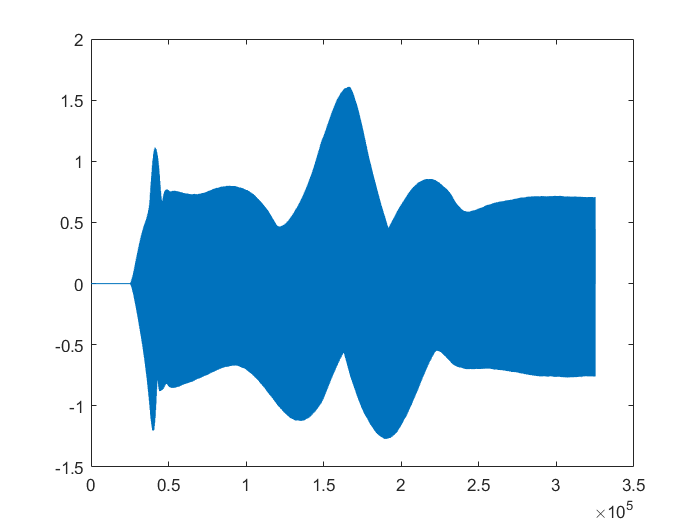




u = data.u(1:end);
plot(u)

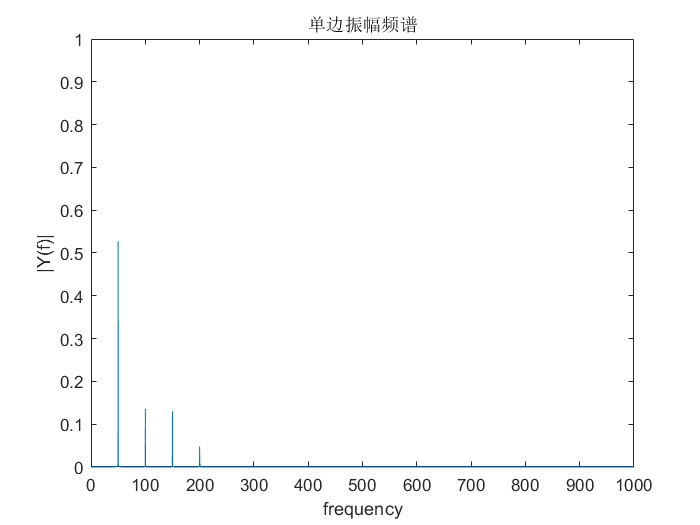

Fs = 5000;

[f, p] = fftFunc(Fs, length(u), u);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 1000])
ylim([0, 1])

function [f, p] = fftFunc(Fs, L, y)
T= 1/Fs; %采样时间
t = (0:L-1)*T; %时间向量
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end